# ME 322 Exercise 1 Report - Introduction to Numerical Simulation and Review of Transfer Functions

**Written by:        **Caiden Bonney - Cal Poly Mechanical Engineering Undergraduate

**Created:**            04/07/2025

**Modified:**           04/13/2025

**Background:    **

This script is a lab report for ME322. This lab exercise is split into two parts, Exercise 1A and Exercise 1B. Exercise 1A simulates the response of a second-order linear ordinary differential equation (ODE) of a mass-spring-damper system driven by a step input forcing function using "ode45" in MATLAB to simulate the mass's displacement, $x_m \left(t\right)$, and velocity, $v_m \left(t\right)$. These are then plotted against time in two plots, $x_m \left(t\right)$ vs $t$ and $v_m \left(t\right)$ vs $t$. In Exercise 1B the transfer function for the mass-spring-damper's ODE from Exercise 1A is calculated symbolically. Using the same system parameters as Exercise 1A with zero initial conditions and a sinusoidal forcing function instead of a step input the displacement is calculated in Simulink using the transfer function. Substituting for a steady-state sinusoidal response the complex transfer function is calculated and used to find the magnitude ratio and the phase shift of the system which are then used to adjust the input sinusoidal forcing function to compare to the results calculated in Simulink. 

**Required Files:**

- ME322_Exercise_1_Matlab.mlx

- ME322_Exercise_1_Simulink.slx

- snapshotModel.m

**References:**

- [1]  ME322_2254_Lab_Manual.pdf

- [2]  ME318_formula_sheet.pdf

## Problem Statement

### Exercise 1A: Introduction to Numerical Simulation

Consider Figure 1 which depicts a parallel mass-spring-damper system consisting of a mass, $m$, spring, $k$, and damper, $b$. The displacement, $x_m$, and velocity, $v_m$, are also labeled in Figure 1 in which positive is to the right. Assume that there is no sliding friction acting on the mass and that due to this gravity has no effect on the mass. Create a simulation describing the displacement and velocity of the system over the period of $0\le t\le 2$ using "ode45" and the function "MBK_state_eqns" defined in the Lab Manual [1].

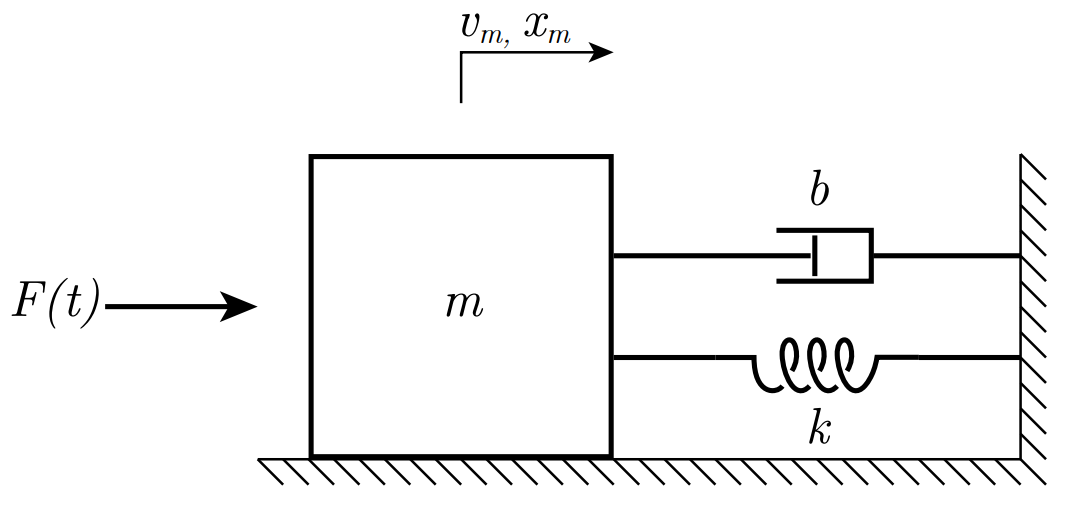

**Figure 1: **Parallel mass-spring-damper [1].

The simulation shall assume the system's initial conditions to be the values noted in Figure 2 and the "MBK_state_eqns" function must be updated to include these initial conditions and system values.

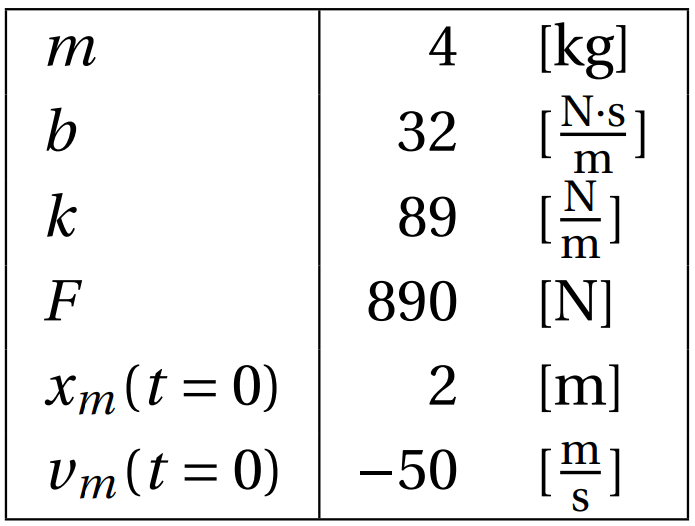

**Figure 2: **Parallel mass-spring-damper physical system parameters [1].

The force, $F$, is a forcing function that begins at time > 0 and remains a constant value of $F=890\;\left\lbrack N\right\rbrack$ which can be modeled as a step-function that begins at $t=0\;\left\lbrack s\right\rbrack$. The first three initial conditions noted in Figure 2, $m$, $k$, and $b$ are to be used for the simulation of the system in Exercise 1B as well. 

Create a figure consisting of two subplots, the Displacement, $x_m$ versus Time, $t$ and Velocity, $v_m$ versus Time, $t$ from $0\le t\le 2$. 

### Exercise 1B: Review of Transfer Functions

Simulate the previous system depicted in Figure 1 using Simulink with the transfer function representation of the system. The forcing function will be a sinusoidal input, $F\left(t\right)=377\sin \left(2t\right)$, and the initial conditions, $x_m \left(0\right)=v_m \left(0\right)=0$. Hand calculaute the transfer function for the differential equation, 

${\textrm{ma}}_m +bv_m +kx_m =F\left(t\right)\;\;;\;t\ge 0$   [1].

Symbolically hand calculate the transfer function and numerically calculate the complex transfer function for a steady-state sinusoidal response in the form of $a+\textrm{bj}$ in MATLAB.

Using these values, calculate the magnitude ratio, $M\left(\omega \right)$, and the phase shift, $\phi \left(\omega \right)$. Plot the input sinusoid and output sinusoid to confirm that the magnitude ratio, $M\left(\omega \right)$, and the phase shift, $\phi \left(\omega \right)$ previously calculated align with the Simulink calculations. 

## Hand Calculations

### **Exercise 1A**

To fill out the missing components of the function "MBK_state_eqns" a vector of the state space system is required in the form $\dot{x} =f\left(x,u,t\right)$.

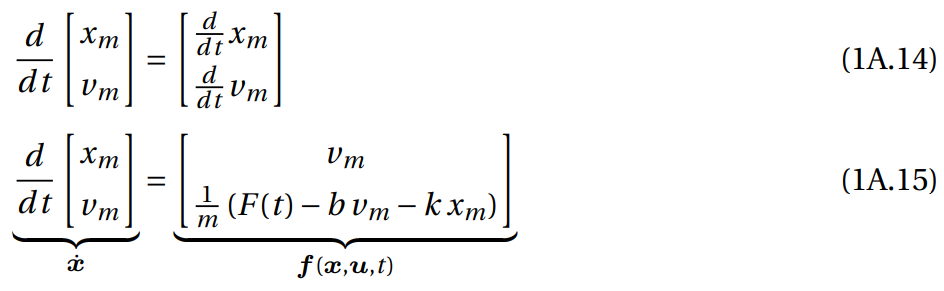

**Figure 3:** Derivative of state vector used by ode45 calculated in the Lab Manual [1].

The initial state vector is created in the Analysis - Exercise 1A section below. The implementation of the vector calculated in Figure 3 is shown below in the Functions section. 

### **Exercise 1B**

Calculating the transfer function, $G\left(s\right)$, for the second-order linear ordinary differential equation given in the Problem Statement section.


$$ma_m +bv_m +kx_m =F\left(t\right)\;\;;\;t\ge 0$$



$$m{\ddot{x} }_m +b{\dot{x} }_m +kx_m =F\left(t\right)\;$$



$$L\left\lbrace m{\ddot{x} }_m +b{\dot{x} }_m +kx_m \right\rbrace =L\left\lbrace F\left(t\right)\right\rbrace \;$$



$$ms^2 x_m \left(s\right)+bsx_m \left(s\right)+kx_m \left(s\right)=F\left(s\right)\;$$



$$\left(ms^2 +bs+k\right)x_m \left(s\right)=F\left(s\right)$$



$$G\left(s\right)=\frac{x_m \left(s\right)}{F\left(s\right)}=\frac{1}{ms^2 +bs+k}$$


Evaluating this transfer function for a steady-state sinusoidal response in which $s=\omega j$


$$G\left(\omega \right)=\frac{1}{k-m\omega^2 +b\omega j}$$


The numerical evaluation of this transfer function to calculate $a+\textrm{bj}$ is done in the Analysis - Exercise 1B section. The magnitude ratio and phase angle are also calculated using MATLAB's functions in this section.

Hand calculating the magnitude ratio and phase shift based on the formula:

$G\left(\omega \right)=\frac{x+yj}{u+vj}$, $M\left(\omega \right)=\frac{\sqrt{x^2 +y^2 }}{\sqrt{u^2 +v^2 }}$, $\phi \left(\omega \right)=\tan^{-1} \left(\frac{y}{x}\right)-\tan^{-1} \left(\frac{v}{u}\right)$   [2].

$G\left(\omega \right)=\frac{x+\textrm{yj}}{u+\textrm{vj}}=\frac{1}{k-m\omega^2 +b\omega j}$ corresponds to $x=1$, $y=0$, $u=k-m\omega^2$, $v=b\omega$, therefore,

$M\left(\omega \right)=\frac{\sqrt{1^2 +0^2 }}{\sqrt{{\left(k-m\omega^2 \right)}^2 +{\left(b\omega \right)}^2 }}$ and $\phi \left(\omega \right)=\tan^{-1} \left(\frac{0}{1}\right)-\tan^{-1} \left(\frac{b\omega }{k-m\omega^2 }\right)$

$M\left(\omega \right)=\frac{1}{\sqrt{{\left(k-m\omega^2 \right)}^2 +{\left(b\omega \right)}^2 }}$ and $\phi \left(\omega \right)=-\tan^{-1} \left(\frac{b\omega }{k-m\omega^2 }\right)$

The numerical evaluation of the magnitude ratio and phase shift are done in the Analysis - Exercise 1B section. 

## Analysis

### **Exercise 1A**

This section will define simulation parameters and run the simulation over a period of 2 seconds.

% Clear workspace of previous MATLAB calculations
clear;

% Initial state vector
x_i = [ 2           % Initial x_m = 2 [m]
        -50 ];      % Initial v_m = -50 [m/s]

% Time span
tspan = [0 2]; % Timespan of 2 seconds

% Function handle associated with Mass-Spring-DamperODE
odefun = @MBK_state_eqns;

% ODE Solution with ode45
[tout, xout] = ode45(odefun, tspan, x_i);

### **Exercise 1B**

This section will define the system parameters used in Simulink and the numerical calculations of the complex transfer function, magnitude ratio, and phase shift. 

% System parameters referenced in Simulink
m = 4;     % [kg]    mass 
b = 32;    % [N*s/m] damping constant
k = 89;    % [N/m]   spring constant

% Forcing function parameters referenced in Simulink 
% f(t) = Asin(wt)
A = 377;   % [N]     Amplitude
w = 2;     % [rad/s] Angular frequency

% Transfer function G(s) when s = wj corresponding to a steady-state
% sinusoidal response 
G = 1/(k-m*w^2 + b*w*1j) 

G = 0.0077 - 0.0068i

% Magnitude ratio of the transfer function corresponding to a steady-state
% sinusoidal response   
abs(G)

ans = 0.0103

% Phase Shift of the transfer function corresponding to a steady-state
% sinusoidal response 
angle(G)

ans = -0.7198

% Referenced in Simulink to create the output sinusoid which was compared
% to the sinusoidal output calculated by Simulink to test for accuracy

% Hand Calculated Magnitude ratio of the transfer function calculated in
% MATLAB to confirm against previously calculated MATLAB value 
M = 1/(sqrt((k-m*w^2)^2+(b*w)^2)) % Value matches previously calculated value 

M = 0.0103

% Hand Calculated Phase Shift of the transfer function calculated in MATLAB
% to confirm against previously calculated MATLAB value 
phi = -atan((b*w)/(k-m*w^2)) % Value matches previously calculated value 

phi = -0.7198

% Define the simulation settings
opt = simset('RelTol', 1e-6);

% Run the simulation for 5 seconds using selected settings simultaneously
% importing the outputs of the simulink file to the MATLAB file
simout = sim("ME322_Exercise_1_Simulink", 5, opt);

## Block Diagram

This section uses "snapshotModel" to take a screen capture of the current block model displayed in "ME322_Exercise_1_Simulink". "ME322_Exercise_1_Simulink" contains the block diagram for the Simulink simulation of the parallel mass-spring-damper system.

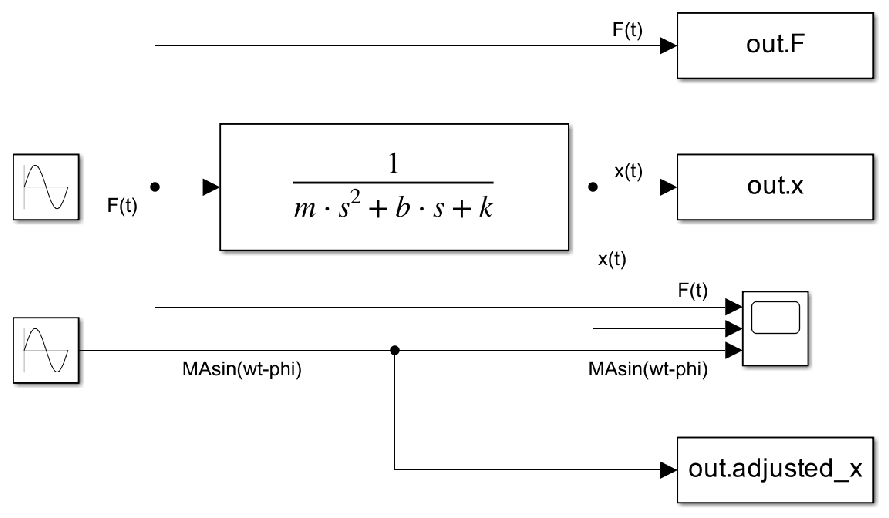

snapshotModel("ME322_Exercise_1_Simulink");

**Figure 4:** Block Diagram for the parallel mass-spring-damper system in Simulink

## Plots

### Exercise 1A

#### **Plots 1 and 2 - Displacement versus Time and Velocity versus Time**

This section graphs two plots. The first plot will show the displacement of the mass as a function of time. The second plot will show the velocity of the mass as a function of time.

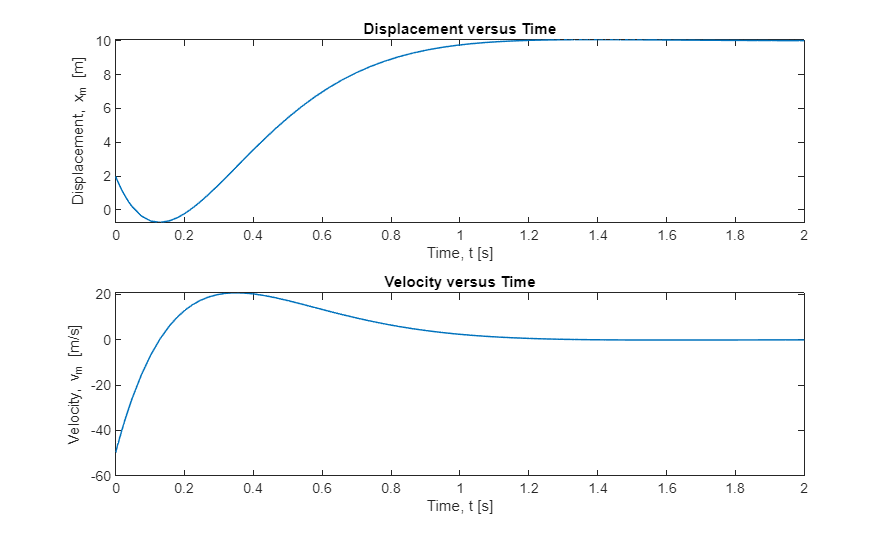

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]);
% Create the first subplot
subplot(2,1,1);
    plot(tout, xout(:, 1), LineWidth=1);
    % Label the axes and add a subplot title
    xlabel("Time, t [s]");
    ylabel("Displacement, x_m [m]");
    title("Displacement versus Time");
% Create the second subplot
subplot(2,1,2);
    plot(tout, xout(:, 2), LineWidth=1);
    % Label the axes and add a subplot title
    xlabel("Time, t [s]");
    ylabel("Velocity, v_m [m/s]");
    title("Velocity versus Time");

**Figure 5:** Displacement, $x_m$ versus Time, $t$ and Velocity, $v_m$ versus Time, $t$ from $0\le t\le 2$ for the parallel mass-spring-damper system

### Exercise 1B

#### **Plot 3 and 4 - Force versus Time and Displacement versus Time**

This section graphs two plots. The first plot will show the forcing function as a function of time. The second plot will show the displacement of the mass as a function of time calculated through Simulink and through adjusting the input steady-state sinusoidal input by the magnitude ratio and phase shift calculated in Analysis - Exercise 1B section.

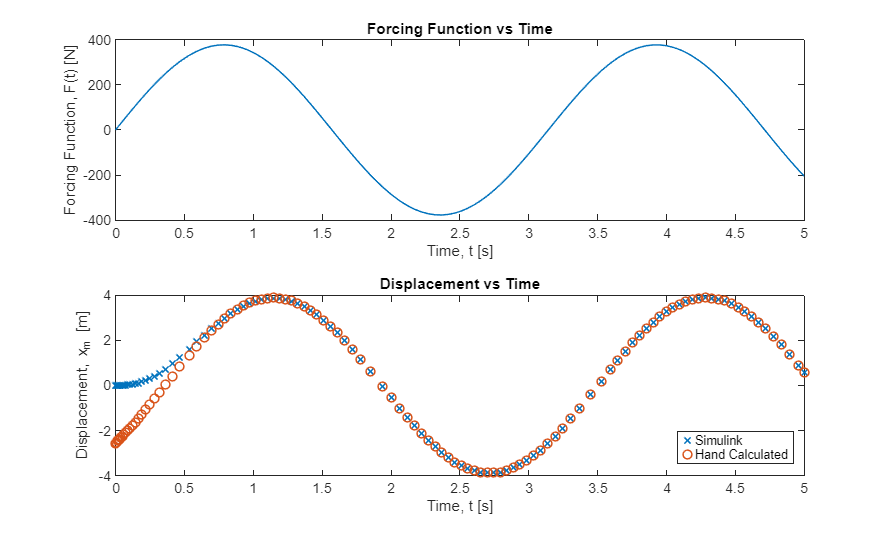

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]);
tiledlayout("vertical");
% Create the first subplot
nexttile;
    plot(simout.tout, simout.F, LineWidth=1);
    % Label the axes and add a subplot title
    xlabel("Time, t [s]");
    ylabel("Forcing Function, F(t) [N]");
    title("Forcing Function vs Time");
% Create the second subplot
nexttile;
    plot(simout.tout, simout.x, "x", DisplayName ="Simulink", LineWidth=1);
    % Label the axes and add a subplot title
    xlabel("Time, t [s]");
    ylabel("Displacement, x_m [m]");
    title("Displacement vs Time");
    % hold and plot Hand Calculated values from Simulink before turning
    % hold off in case of future plots
    hold on 
    plot(simout.tout, simout.adjusted_x, "o", DisplayName ="Hand Calculated", LineWidth=1);
    hold off
    % Add a legend due to multiple lines on a single plot
    legend(Location="southeast");

**Figure 6:** Forcing Function, $F\left(t\right)$ versus Time, $t$, and Displacement, $x_m$ versus Time, $t$ from $0\le t\le 5$ for the parallel mass-spring-damper system. The displacement graph consists of Simulink simulation and hand calculation responses.

## Discussion Questions

### Exercise 1A

#### Question 1

*Suppose we had a third-order system, still in the dependent variable xm. What would be a valid choice of state variables for such a system? Provide a specific set of state variables along with a description of each variable.* 

In a third-order system in which the dependent variable is $x_m$ the linear ODE must fit into the form of:


$$a_3 \frac{{{\mathrm{d}}^3 x}_m }{\mathrm{d}t^3 }+a_2 \frac{{{\mathrm{d}}^2 x}_m }{\mathrm{d}t^2 }+a_1 \frac{\mathrm{d}x_m }{dt}+a_0 x_m =F\left(t\right)\;$$


Following the same format for the state vector as described in the Functions section a third-order derivative state vector has 3 rows in which each row is the derivative of the last. 


$$x=\left\lbrack \begin{array}{c}
x_m \\
{\dot{x} }_m \\
{\ddot{x} }_m 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$


The derivative of the state vector consists of the form:


$$\dot{x} =\left\lbrack \begin{array}{c}
x_2 \\
x_3 \\
\frac{1}{a_3 }\left(F\left(t\right)-a_2 x_3 -a_1 x_2 -a_0 x_1 \right)
\end{array}\right\rbrack$$


Following this format there are three state variables, 

$x_1 =x_m$ (Displacement)

$x_2 ={\dot{x} }_m$ (Velocity) 

$x_3 ={\ddot{x} }_m$ (Acceleration)

which correspond to each derivative of the dependent variable in the linear ODE except that highest order derivative. Taking the derivative of the state vector to input into the MATLAB function to be used with "ode45" and writing this state vector in terms of the state variables the last row is equivalent to the highest order derivative in the linear ODE so after solving for that derivative it should be placed in the last row of the derivative of the state vector, $\dot{x}$. 

$x_m^{\left(3\right)} =\frac{1}{a_3 }\left(F\left(t\right)-a_2 x_3 -a_1 x_2 -a_0 x_1 \right)$ (Jolt)

#### Question 2

*For this system, the input F(t) is treated as a step input. That is, the input “turns on” at time zero, but has a value of zero for negative time. This is easy to handle in the ODE function because the simulation starts at time zero, so the input is effectively constant during the simulation time. *

*Suppose we wanted simulate the system response starting at t = 0 but we also want to delay the input by one second so that the input “turns on” at t =1 instead of at t = 0. How would you adjust your ODE function to account for this one second delay? *

*Do not actually modify your function file to implement the delay in the step input. However,consider using an example code snippet to supplement your answer to this question. You can insert example code using the “Insert” tab in the live editor so that it will format as text in your report submission without MATLAB™ trying to run the code in your example*

To implement a 1-second delay in the step input $F\left(t\right)$ for the system, the ODE function can be modified to conditionally assign the value of the forcing function based on the current simulation time. Since the simulation begins at $t=0$, and we want the input to “turn on” at $t=1$, we use an if statement to set the value of $F$ accordingly. 

Below is an adjustment of the "MBK_state_eqns" function to include this delay in the forcing function's application.

#### Question 3

*For this system, there are two ways energy can be stored - in potential energy or kinetic energy. The system also dissipates energy over time, as illustrated by the exponential decay visible in your plot.*

*Identify which parts of the model store energy and what type of energy they each store; additionally, determine which state variables are associated with each type of energy storage. Also identify which parts of the model dissipate energy. *

*Is it a coincidence that the number of state variables matches the number of different ways energy can be stored in the system?*

Below is an adjustment of the "MBK_state_eqns" function to include this delay in the forcing function's application. Is it a coincidence that the number of state variables matches the number of different ways energy can be stored in the system?

In the simulated mass-spring-damper system, energy can be stored in two forms, kinetic energy and potential energy. The mass stores the kinetic energy in the form of velocity, while the spring stores the potential energy associated with the displacement of the mass from its equilibrium position. These two forms of stored energy correspond directly to the two-state variables, velocity and displacement. 

The system also dissipates energy over time through the included damper in the system. The damper converts mechanical energy into heat through viscous friction. The damper does not store energy and therefore does not contribute an additional state variable to the system it just removes energy from the system.

It is not a coincidence that the number of state variables matches the number of ways that energy can be stored. When modeling systems the number of independent energy-storing components is equal to the number of state variables because each component requires its own differential equation to describe how the energy flows into and out of that storage. However, these energy-storing components must be independent to add an additional state variable. For example, if a secondary spring was added to the system parallel to the existing spring both springs would act on the same mass and therefore both springs would be dependent upon the same velocity. Due to both springs being dependent upon the same velocity they can be combined into a single equivalent spring and therefore the system would remain at second order. 

It is also important to note that the number of state variables does not match the number of types of energy stored in the system but the number of independent energy-storing components. It also does not match the number of energy-storing components in total as some of these components are dependent and can be modeled through a single independent equivalent component. Dissipative components such as dampers change the behavior of the system in that there is decay occurring however, they do not necessarily change the order of the system.

### Exercise 1B

#### Question 1

*Specifically, what does the simulation output represent? Is the simulation output in the time domain or the frequency/Laplace domain?* 

The simulation output from the "transfer function" block in Simulink is the response of the system in the Laplace domain, $x_m \left(s\right)$, to the input, $F\left(s\right)$. Simulink automatically applies the Laplace transformation to the input "sine wave" block and the inverse Laplace transformation to the "scope" and "to workspace" blocks. This is why the scope displays the results in the time domain rather than the frequency domain.  

#### Question 2

*The denominator of the transfer function is a polynomial describing the fundamental dynamics associated with the system. *

*(a) What is the formal name for this polynomial? *

The formal name for the denominator of the transfer function is a characteristic polynomial.

*(b) What information can you find from the roots of this polynomial? *

The roots of the characteristic polynomial define the behavior of the system during free response. The real part of each root denotes whether the system is stable, unstable, or constant, negative = stable, positive = unstable, zero = undamped. The imaginary part of each root describes the frequency of the oscillation. If the imaginary component of the root is nonzero, the system will oscillate at that angular frequency. 

Combining this information the real component of each root determines whether the system will decay (stable), grow (unstable), or remain constant (undamped) while the imaginary component will denote the frequency at which this will occur in which the imaginary component directly equals the angular frequency of the sinusoidal response. The overall response of the system is a combination of all of these roots together. 

The current system we are modeling has a characteristic polynomial of $4s^2 +32s+89$ calculating the roots of this polynomial by solving for the homogeneous equation:


$$\begin{array}{l}
4s^2 +32s+89=0\\
s^2 +8s+22\ldotp 25=0\\
s=\frac{-8\pm \sqrt{8^2 -4\left(1\right)\left(22\ldotp 25\right)}}{2\left(1\right)}\\
s=\frac{-8\pm 5\sqrt{-1}}{2}\\
s=-4\pm \frac{5}{2}j\\
s_1 ,s_2 =-4\pm 2\ldotp 5j
\end{array}$$


Due to the negative real components of the roots, the system is stable and will therefore decay over time, as expected for damped systems. It will oscillate at an angular frequency of $2\ldotp 5\;\left\lbrack \frac{\mathrm{rad}}{s}\right\rbrack$ over the course of its decay. Both parts of Exercise 1 assume a forcing function input, therefore, the displacement outputs may not match these values exactly due to the total response of the system consisting of the sum of the homogeneous solution (free response) and the particular solution (forced response). Due to the decaying characteristic of the homogeneous solution found previously over a long period of time, the free response of the system will decay until only the forced response remains. 

*(c) If you know the amplitude and frequency of the forcing function, what else can you find from the roots of the polynomial?* 

If the amplitude, $A_{\mathrm{forced}}$, and frequency, $\omega_{\mathrm{forced}}$, of the forcing function are known, assuming a sinusoidal input the total response of the system can be calculated based on the roots of the polynomial. This was actually done in Exercise 1B of this report in which the particular solution of the system was hand-calculated and plotted against the total system solution calculated in Simulink in Figure 6. The magnitude ratio, $M\left(\omega \right)$, and phase shift, $\phi \left(\omega \right)$, are calculated based on the polynomial roots and substituting the given frequency of the forcing function for $\omega$. Then the particular solution of the system is in the form of:


$$x_{\mathrm{part}} \left(t\right)=A_{\mathrm{forced}} M\left(\omega_{\mathrm{forced}} \right)\sin \left(\omega_{\mathrm{forced}} t-\phi \left(\omega_{\mathrm{forced}} \right)\right)\;$$


This function was input into Simulink in Exercise 1B and graphed in Figure 6 under the lablel "Hand Calculated". The difference at the start of the plot is due to the homogenous solution to the system:


$$x_{\mathrm{homo}} \left(t\right)=e^{-4t} \left(C_1 \cos \left(2\ldotp 5t\right)+C_2 \sin \left(2\ldotp 5t\right)\right)$$


In which $C_1$ and $C_2$ are based on the initial conditions of the system which in the case of Exercise 1B $x_m \left(0\right)=v_m \left(0\right)=0$. Due to these initial conditions $C_1 =C_2 =0$. Therefore the homogeneous solution of the system is $x_{\mathrm{homo}} \left(t\right)=0$ which is why the mass matched the particular solution graphed in Figure 6 as soon as it could based on its initial conditions of $x_m \left(0\right)=v_m \left(0\right)=0$. 

#### Question 3

*How could you modify the numerator of the transfer function to produce the derivative of the system output? What expression would you enter into the transfer function block parameters to select this new numerator?* 

By multiplying the numerator by an additional $s$ the system would output the derivative of the current system output. Doing this change the new transfer function is:

$G\left(s\right)=\frac{x_m \left(s\right)}{F\left(s\right)}=\frac{1}{ms^2 +bs+k}$ (Original Transfer Function)


$$s*G\left(s\right)=\frac{s}{ms^2 +bs+k}$$


$\frac{\frac{\mathrm{d}}{\mathrm{dt}}x_m \left(t\right)}{F\left(t\right)}=L^{-1} \left\lbrace \frac{s}{ms^2 +bs+k}\right\rbrace$ (Derivative of the output of the transfer function)

The expression input into the transfer function block would be $\frac{s}{ms^2 +bs+k}$. 

The parameters of the transfer function block would be:

Numerator coefficients = [1 0]

Denominator coefficients = [m b k]

#### Question 4

*The initial conditions specified in the background of the assignment are both zero. Is it possible to use a transfer function representation to consider systems with non-zero initial conditions? *

In the current form of the transfer function in which the transfer function block is in the form of one equation, we cannot model non-zero initial conditions. However, if the transfer function was to be broken up into its constituent integrator blocks in which the block diagram is completely modeled using integrator, summing junctions, and constant gain blocks the initial conditions can be specified in the integrator blocks.  

#### Question 5

*For the second-order system in this assignment, is there a driving frequency ω, that would result in a 180◦ phase shift? If it is possible, determine the value of ω that would cause such a phase shift; if it is not possible, explain why it is not possible and consider if other systems of different order could reach such a phase shift.* 

The the second-order system in this assignment there is no driving frequency $\omega$ that will result in a 180 degree phase shift. As previously stated in the Hand Calculations - Exercise 1B section:

$G\left(\omega \right)=\frac{x+\textrm{yj}}{u+\textrm{vj}}$, $M\left(\omega \right)=\frac{\sqrt{x^2 +y^2 }}{\sqrt{u^2 +v^2 }}$, $\phi \left(\omega \right)=\tan^{-1} \left(\frac{y}{x}\right)-\tan^{-1} \left(\frac{v}{u}\right)$   [2].

$G\left(\omega \right)=\frac{x+yj}{u+vj}=\frac{1}{k-m\omega^2 +b\omega j}$ corresponds to $x=1$, $y=0$, $u=k-m\omega^2$, $v=b\omega$, therefore,

$M\left(\omega \right)=\frac{\sqrt{1^2 +0^2 }}{\sqrt{{\left(k-m\omega^2 \right)}^2 +{\left(b\omega \right)}^2 }}$ and $\phi \left(\omega \right)=\tan^{-1} \left(\frac{0}{1}\right)-\tan^{-1} \left(\frac{b\omega }{k-m\omega^2 }\right)$

$M\left(\omega \right)=\frac{1}{\sqrt{{\left(k-m\omega^2 \right)}^2 +{\left(b\omega \right)}^2 }}$ and $\phi \left(\omega \right)=-\tan^{-1} \left(\frac{b\omega }{k-m\omega^2 }\right)$

Based on the equation for phase shift, $\phi \left(\omega \right)=\tan^{-1} \left(\frac{y}{x}\right)-\tan^{-1} \left(\frac{v}{u}\right)$, the only way in which there is a 180 degree phase shift is for, $\tan^{-1} \left(\frac{y}{x}\right)=\pm 90$ and ${-\tan }^{-1} \left(\frac{v}{u}\right)=\pm 90$. However, after plugging in the x, y, v, u based on the transfer function of the system the phase shift is $\phi \left(\omega \right)=\tan^{-1} \left(\frac{0}{1}\right)-\tan^{-1} \left(\frac{b\omega }{k-m\omega^2 }\right)$. Since the first inverse tangent will always evaluate to zero, the largest phase shift possible for the current system is $\pm 90$. Therefore there is no 180 degree phase shift. 

If a system had a transfer function of:


$$\frac{x_m \left(s\right)}{F\left(s\right)}=\frac{s}{ms^2 +bs+k}$$


then the phase angle would be 


$$\phi \left(\omega \right)=\tan^{-1} \left(\frac{-\omega }{0}\right)-\tan^{-1} \left(\frac{b\omega }{k-m\omega^2 }\right)$$


In this system it would be possible for a 180 degree phase shift if the denominator of the second inverse tangent was equal to 0,


$$k-m\omega^2 =0$$



$$\omega =\sqrt{\frac{k}{m}}$$


When this system runs on a sinusoidal input with this frequency there would be a 180 degree phase shift


$$\phi \left(\omega \right)=\tan^{-1} \left(\frac{-\sqrt{\frac{k}{m}}}{0}\right)-\tan^{-1} \left(\frac{b\sqrt{\frac{k}{m}}}{0}\right)=-\frac{\pi }{2}-\frac{\pi }{2}=-\pi \;\left\lbrack \mathrm{rad}\right\rbrack \approx 180\;\left\lbrack \deg \right\rbrack$$


## Functions

### Mass-Spring-Damper Equations of Motion

The MBK_state_eqns is a function designed for use with "ode45". The function models the ODE for a mass-spring-damper system consisting of a second-order ordinary differential equation. To be used with MATLAB's "ode45" its inputs include a time variable, $t$, and a state vector $x$, in which the output is the differentiation of the state vector, $\dot{x}$. The state vector is a matrix with $n$ rows for a $n$th order ordinary differential equation in which each row is equal to the derivative of the last. 

**Original ODE:**


$${\ddot{x} }_m =\frac{1}{m}\left(F\left(t\right)-b{\dot{x} }_m -kx_m \right)$$


**State Vector:**


$$\begin{array}{l}
x=\left\lbrack \begin{array}{c}
x_m \\
{\dot{x} }_m 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \\
\dot{x} =\left\lbrack \begin{array}{c}
x_2 \\
\frac{1}{m}\left(F\left(t\right)-bx_2 -kx_1 \right)
\end{array}\right\rbrack 
\end{array}$$


function [xd] = MBK_state_eqns(t, x) %#ok<INUSD>
m = 4;     % [kg]    mass 
b = 32;    % [N*s/m] damping constant
k = 89;    % [N/m]   spring constant
F = 890;   % [N]     forcing function

% Differential equation
xd = [ x(2)                   % [m/s]   x_md  (v_m)
       (F-b*x(2)-k*x(1))/m ]; % [m/s^2] x_mdd (a_m)
end